Let's start by seting up the path.

clear
clc

full_path='D:\MATLAB AP Package Beta\';
project_path='D:\MATLAB AP Package Beta\Scratch\Week 5\';

addpath(genpath([full_path,'Data\']));
addpath(genpath([full_path,'Functions\']));
cd(project_path);

if ~exist([project_path, 'Data'], 'dir')
    mkdir([project_path, 'Data'])
end
addpath(genpath(project_path));

clear full_path project_path  

## Amihud (2002)

Let's start with replicating Amihud (2002). We can get quite closely qualitatively with just a few lines of code. The cookbook creates the Amihud measure in the makeCRSPDailyDerivedVariables() function that is called by setup_library.m, so we can just load and replicate his results:

clear
clc

load amihud
load ret
load dates
load exchcd
load betas

nStocks = size(ret, 2);
decInd = (dates - 100*floor(dates/100) == 12);
rptdDecInd = 1*repmat(decInd, 1, nStocks);
rptdDecInd(~decInd, :) = nan;

R30 = makePastPerformance(ret, 3, 0) .* rptdDecInd;
R124 = makePastPerformance(ret, 12, 3) .* rptdDecInd;
beta = bstd .* rptdDecInd;

illiqma = rptdDecInd .* amihud ./ repmat(mean(amihud, 2, 'omitnan'), 1, nStocks);

runFamaMacBeth(100*ret, [beta illiqma R30 R124],dates);

% NYSE stocks & matching period:
ret(exchcd~=1) = nan;
amihud(exchcd~=1) = nan;

illiqma = amihud ./ repmat(nanmean(amihud, 2), 1, size(ret, 2));

runFamaMacBeth(100*ret, [beta illiqma R30 R124],dates, 'timePeriod', [196401 199612]);

Compare with:

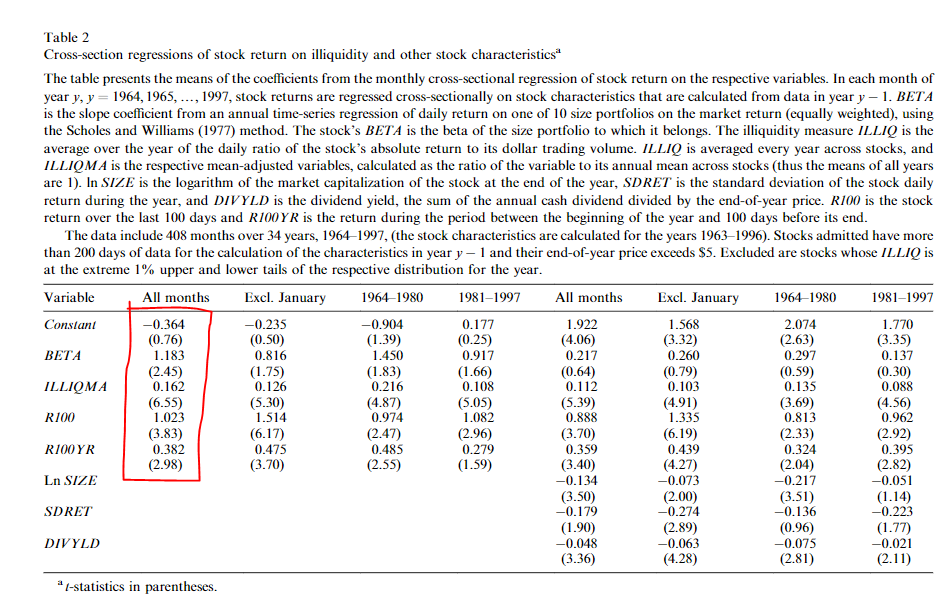

The quick replication above gets us super close. We can try to do a more involved replication, and my best attempt at that is below. First we'll calculate the illiquidity measure, which is given by:


$${\mathrm{ILLIQ}}_{i\;y} =\frac{1}{D_{\mathrm{iy}\;} }\sum_{t=1}^{D_{\mathrm{iy}} } |R_{\mathrm{iyd}} |/{\mathrm{VOLD}}_{\mathrm{ivyd}\;}$$


It is subject to the following filters:

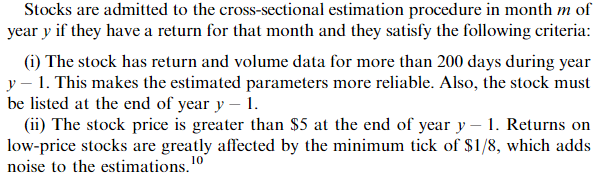

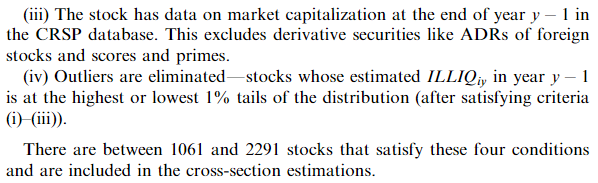

clear
clc

load dret
load dvol
load dates
load ret
load ddates
load prc
load dprc
load me

% Store the years
nMonths = length(dates);

illiq = nan(size(ret));

dvol(dvol==0) = nan;

dprc = abs(dprc);
prc = abs(prc);
a = abs(dret)./(dvol.*dprc);

clear dret dvol

for i=13:12:nMonths
    dates(i)
    indexYear = find( floor(ddates/100) >= dates(i-11) & ...
                      floor(ddates/100) <= dates(i) ); 
    ind=(  sum( isfinite(a(indexYear,:)), 1) > 200  )   &   prc(i,:)>5 & isfinite(me(i, :));
    illiq(i, ind) = mean(a(indexYear, ind), 1, 'omitnan');
end

save Data\illiq illiq

Now that we have the stock-year illiquidity measure, we are ready to replicate the Table 2 Fama-MacBeth results. 

Let's start by loading the relevant variables:

clear
clc

load illiq
load exchcd
load ret
load dates
load dret
load ddates
load dme
load dff
load me

Next, we'll crate a few indices that we'll make use of later:

% Create a few indices 
decInd = dates - 100*floor(dates/100) == 12;        % December
eomInd = find(eomflag==1);                          % End-of-month index
eoyInd = eomInd(decInd);                            % End-of-year index

Use the eoyInd and decInd indices to get a daily exchange code matrix:

% Create

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0       -0.126       -0.241 
                    var 1        1.174        2.311 
                    var 2        0.085        3.467 
                    var 3        1.228        3.950 
                    var 4        0.455        2.510 

---------------------------------------------------------------------- 


dexchcd = nan(size(dme));
dexchcd(eoyInd, :) = exchcd(decInd, :);

Let's create the ten size portfolios for the calculation of the betas. All of the functions (e.g., runUnivSort, runBivSort) should work with daliy data as well, though I have not extensively test that. Here we'll leave the dme observatoins for which the  exchange code is not 1 (i.e., not on the NYSE). Since the dexchcd matrix also only has values for the end-of-year days, we'll effectively have daily returns to 10 portfolios created by sorting into deciles based on market and rebalancing at the end of each year:

tempDme = dme;
tempDme(~ismember(dexchcd, [1]))=nan;
ind = makeUnivSortInd(tempDme,10);
dres = calcPtfRets(dret, ind, dme, 1, 'e');   

We'll also need the daily CRSP equal-weighted index only from the NYSE stocks, so we need to create it, which is somewhat involved. 

dexchcd = FillMonths(dexchcd);
dexchcd(isnan(dret)) = nan;
dret(~ismember(dexchcd, [1])) = nan;
dret(isnan(FillMonths(illiq)))=nan;
crspEW = mean(dret, 2, 'omitnan');

We'll also initialize the ret100 and ret100yr variables and create a datetime for the daily dates to use to determine the 100 days cutoff:

ret100   = nan(size(ret));
ret100yr = nan(size(ret));
ddates_dt = datetime(ddates, 'ConvertFrom', 'yyyyMMdd');

Sort on size only within NYSE stocks with the monthly data too, to know where to assign the betas.

tempME = me;
tempME(~ismember(exchcd, [1])) = nan;
indME10 = makeUnivSortInd(tempME,10);

Let's loop over the Decembers and calculate the betas and the return variables. In my library, the first monthly date is 192512, so I'll start at 13 (i.e., 192612).

The Scholes and Williams betas are estimated using Equation (20) from their 1977 paper:

where:

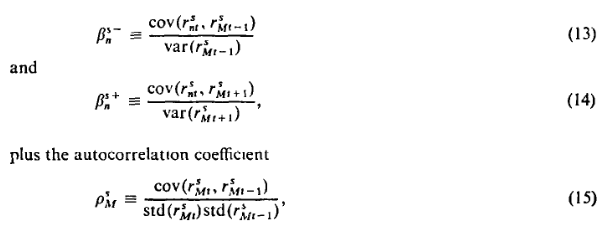

beta = nan(size(ret));
for i=13:12:length(eomInd)
    begInd = eomInd(i-12)+1;
    endInd = eomInd(i);    
    
    % Beta, Scholes and Williams method
    rho = corrcoef(crspEW(begInd:endInd-1), crspEW(begInd-1:endInd-2));
    const = ones(size(ddates(begInd:endInd-1)));
    for j = 1:10
        res1 = nanols(dres(begInd:endInd-1,j), [const crspEW(begInd-1:endInd-2)]);
        res2 = nanols(dres(begInd:endInd-1,j), [const crspEW(begInd:endInd-1)]);
        res3 = nanols(dres(begInd:endInd-1,j), [const crspEW(begInd+1:endInd)]);
        
        beta(i,indME10(i,:)==j) = (res1.beta(2) + res2.beta(2) + res3.beta(2)) ./ (1 + 2*rho(1,2));
    end
    
    %Return variables
    d100Ind = find(days(ddates_dt-ddates_dt(endInd)) <= -100, 1, 'last');
    
    temp = cumprod(1+dret(d100Ind+1:endInd,:)) - 1;
    ret100(i,:) = temp(end,:);
    
    temp = cumprod(1+dret(begInd+1:d100Ind,:)) - 1;
    ret100yr(i,:) = temp(end,:);       
end


Let's apply their last filter here:

nStocks = size(ret, 2);

ind = (isnan(illiq) | ...
       exchcd ~= 1 | ...
       illiq > repmat(prctile(illiq, 99, 2), 1, nStocks) | ...
       illiq < repmat(prctile(illiq, 1, 2), 1, nStocks) );
illiq(ind) = nan;
beta(ind) = nan;
ret100(ind) = nan;
ret100yr(ind) = nan;

Amihud (2002) uses the cross-sectional mean of $\textrm{ILLIQ}$:


$${\textrm{AILLIQ}}_y =\frac{1}{N_{y\;} }\sum_{t=1}^{N_y } {\textrm{ILLIQ}}_{\textrm{iy}\;}$$


to define the mean-adjusted illiquidity measure:


$${\textrm{ILLIQMA}}_{\textrm{iy}} ={\textrm{ILLIQ}}_{\textrm{iy}} /{\textrm{AILILIQ}}_y$$


which we'll use in the Fama-MacBeth below. 

ailliq = repmat(mean(illiq, 2, 'omitnan'), 1, nStocks);
illiqma = illiq./ailliq;

An here is the Fama-MacBeth:

runFamaMacBeth(100*ret, [beta illiqma ret100 ret100yr], dates, 'timePeriod', [196401 199712]);

## Pastor and Stambaugh (2003)

Now let's do Pastor and Stambaugh (2003). Their goal is to develop a market-wide, systematic liquidity factor. The procedure goes as follows:

- Start by estimtaing individual stock liquidity, $\gamma_{i,t}$ from:


$$r_{i,d+1,t}^{e\;} =\theta {\;}_{i,t} +\phi {\;}_{i,t\;} r_{i,d,t} +\gamma_{i,t} \textrm{sign}\left(r_{i,d,t}^{e\;} \right)\ldotp v_{i,d,t} +\epsilon_{i,d+t,t\;}$$


where $r_{i,d+1,t}^{e\;} \equiv r_{i,d,t} -r_{m,d,t}$

- Aggregate individual stock liquidity for each month:


$$\hat{\gamma_{t\;} \;} =\frac{1}{N\;}\sum_{i=1}^N \hat{\;\gamma_{i,t} }$$


- Get its innovations as the unexpected changes in scaled aggregate liquidity (i.e., L_t from the regression):


$$\Delta \;\hat{\gamma_{t\;} \;} =a+b\Delta \;\hat{\gamma_{t-1} \;} +c\left(\frac{m_{t-1} }{m_{t\;} }\right)\hat{\gamma_{t-1\;} \;} +100L_t$$


where $\Delta \;\hat{\gamma_{t\;} \;} =\left(\frac{m_t }{m_1 }\right)\frac{1}{N_t }\sum_{i=1}^{N_t } \left(\;\hat{\gamma_{i,t\;} \;} -\hat{\gamma_{\textrm{it},-1\;} \;} \right)$ and $m_t$ is the total market cap of all eligible stocks in month t-1

- Get a traded factor by estimating historical betas and forming form long/short portfolios:


$$r_{i,t}^e =\beta_i^0 +\beta_i^L {\;L}_t +\beta_i^M {\textrm{MKT}}_t +\beta_i^S {\;\textrm{SMB}}_{t\;} +\beta_i^H \;{\textrm{HML}}_t +\epsilon_{i,t}$$


We'll start by loading the variables and creating a few things we'll need later:

clear
clc

load dvol
load dprc
load dret
load dates
load ddates
load ret
load exchcd
load prc
load dff

[nMonths, nStocks] = size(ret);

xret = dret - repmat(dmkt, 1, nStocks);
dollar_volume = dvol.*abs(dprc)/10e5;
dollar_volume(dvol<=0) = nan;
signedVol = sign(xret) .* dollar_volume;

s = find(dates==196208);
e = find(dates==199912);

Now let's work on the sample selection:

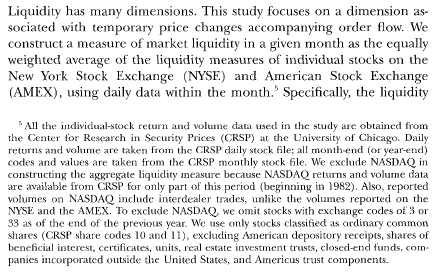

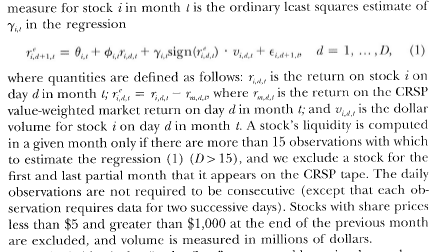

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                      
               1    0.558   -0.135    1.162    0.267   -0.115   -0.035
                  [ 2.45]  [-1.41]  [51.44]  [ 8.35]  [-3.37]  [-1.51]
                                                                      
               2    0.641   -0.009    1.043   -0.004    0.091    0.002
                  [ 3.45]  [-0.13]  [60.90]  [-0.15]  [ 3.52]  [ 0.09]
                                                                      
               3    0.541   -0.069    0.993   -0.114    0.053    0.037
                  [ 3.17]  [

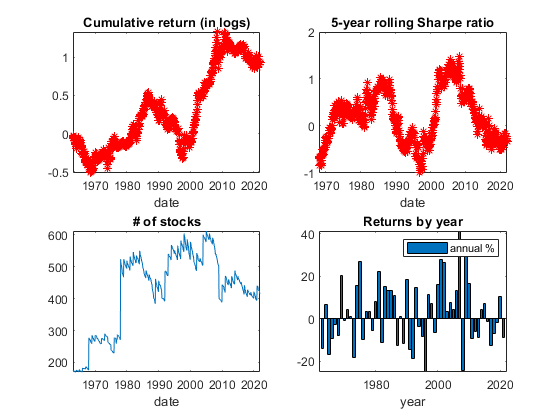

lprc = lag(abs(prc), 1, nan);

% Set the universe 
ps_universe = 1*isfinite(ret);
indToDrop = (exchcd~=1 & exchcd~=2) | ...
            lprc <= 5 | ...
            lprc >= 1000;
ps_universe(indToDrop) = 0;

% This loop takes care of the condition that they exclude first and last partial month a stock appears on CRSP
for c = 1:nStocks 
    r = find(isfinite(dret(:,c)), 1, 'first');

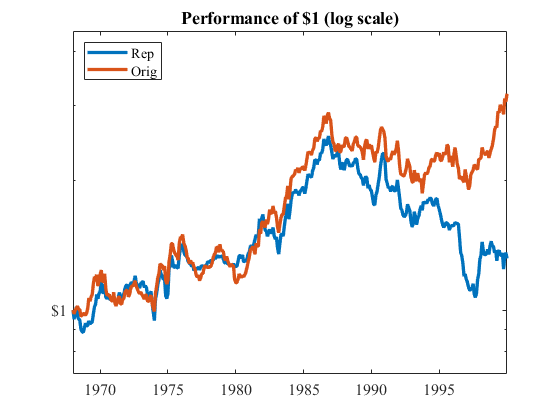

    if r>1
        if eomflag(r-1)==0
            iMonth = find(dates==floor(ddates(r)/100));
            ps_universe(iMonth, c) = 0;
        end
    end

    r = find(isfinite(dret(:,c)), 1, 'last');

Unrecognized function or variable 's'.

    if eomflag(r)==0
        iMonth = find(dates==floor(ddates(r)/100));        
        ps_universe(iMonth, c) = 0;
    end
end  


Now let's work on estimating Equation (1):


$$r_{i,d+1,t}^{e\;} =\theta {\;}_{i,t} +\phi {\;}_{i,t\;} r_{i,d,t} +\gamma_{i,t} \textrm{sign}\left(r_{i,d,t}^{e\;} \right)\ldotp v_{i,d,t} +\epsilon_{i,d+t,t\;}$$


gamma = nan(nMonths, nStocks);

for i = s-1:nMonths
    indMonth = find(floor(ddates/100) == dates(i));
    
    olsVars = xret(indMonth,:) + dret(indMonth-1,:) + dollar_volume(indMonth-1,:);
    numObs = sum(isfinite(olsVars), 1);
    numNonZeroRetObs = sum(abs(dret(indMonth(1)-1:indMonth(end), :)) > 0, 1);
    
    hor_ind = find(numObs > 15 & numNonZeroRetObs >= 3);
    const = ones(length(indMonth), 1);
    for j = hor_ind
        
        y = xret(indMonth, j);
        x = [const dret(indMonth-1, j) signedVol(indMonth-1, j)];
        temp_res = nanols(y,x);
        gamma(i,j) = temp_res.beta(3);

    end
end
gamma(ps_universe==0) = nan;

save Data\gamma gamma

Now, before we get to constructing the innovations in liquidity and the liquidity factor, let's downlod the posted PS data to compare later:

urlwrite('https://finance.wharton.upenn.edu/~stambaug/liq_data_1962_2020.txt','Data\ps_original.txt');
data = load('ps_original.txt');
data(data==-99) = nan;
[~, ia, ib] = intersect(dates, data(:,1), 'legacy');

PS.Aliq = nan(size(dates));
PS.Dliq = nan(size(dates));
PS.LIQ  = nan(size(dates));

PS.Aliq(ia) = data(ib,2);
PS.Dliq(ia) = data(ib,3);
PS.LIQ(ia)  = data(ib,4);

save Data\PS PS

Next, we'll create the aggregate individual stock liquidity:


$$\hat{\gamma_{t\;} \;} =\frac{1}{N\;}\sum_{i=1}^N \hat{\;\gamma_{i,t} }$$


and scale it by the market cap ratio for calculations of the innovations later:


$$\left(\frac{m_t }{m_1 }\right)\hat{\gamma_t \;}$$


clear
clc

load me
load gamma
load PS
load dates
load pdates

me_t = sum(lag(me,1,nan).*isfinite(gamma), 2, 'omitnan');
s = find(dates==196208);
e = find(dates==199912);

me_factor = me_t / me_t(s);

Aliq = sum(gamma, 2, 'omitnan')./sum(isfinite(gamma), 2, 'omitnan');      % Equation (5)
Aliq = Aliq .* me_factor;                       % scaled series (mt/mt-1)gamma\

prt(nanols(PS.Aliq(s:e),[ones(size(Aliq(s:e))) Aliq(s:e)]));
corrcoef(PS.Aliq(s+1:e), Aliq(s+1:e))
plot(pdates(s:e),[PS.Aliq(s:e) Aliq(s:e)]);


If it looks good, let's construct the innovations in the aggregate liquidity using Equation (7) next:


$$\Delta \;\hat{\gamma_{t\;} \;} =a+b\Delta \;\hat{\gamma_{t-1} \;} +c\left(\frac{m_{t-1} }{m_{t\;} }\right)\hat{\gamma_{t-1\;} \;} +100L_t$$


 That is the non-traded factor we'll use to estimate the betas later.

dgamma = gamma - lag(gamma,1,nan);
Dgamma = sum(dgamma, 2, 'omitnan') ./ sum(isfinite(dgamma),2);      % Equation (6)
Dgamma = Dgamma .* me_factor;                                    

Dliq = nan(size(dates));

res = nanols(Dgamma(s:e), [ones(size(Dgamma(s:e)))  Dgamma(s-1:e-1)  Aliq(s-1:e-1)]);
Dliq(s+1:e) = res.resid;   

prt(nanols(PS.Dliq(s:e),[ones(size(Aliq(s:e))) Dliq(s:e)]));
corrcoef(PS.Dliq(s+1:e), Dliq(s+1:e))
plot(pdates(s:e),[PS.Dliq(s:e) Dliq(s:e)]);
legend('PS','Replication');

If everything looks good so far, let's store our replication data:

REP.dates = dates;
REP.Aliq = Aliq;
REP.Dliq = Dliq;
REP.Dgamma = Dgamma;

save Data\PS_REP REP

Now that we have the non-traded liquidity factor, we need to estimated the beta that we'll use to construct the traded factor. For that, we'll use equation (9):


$$r_{i,t}^e =\beta_i^0 +\beta_i^L {\;L}_t +\beta_i^M {\textrm{MKT}}_t +\beta_i^S {\;\textrm{SMB}}_{t\;} +\beta_i^H \;{\textrm{HML}}_t +\epsilon_{i,t}$$


and to avoid look-ahead bias they re-estimate${\;L}_t$ each December with data only available until that point. 

Start by loading the variables;

clear
clc

load dates
load permno
load ret_x_dl % beta_hist is calculated using return without dlret
load me
load prc
load ret
load vol
load shrout
load exchcd
load NYSE
load ff
load PS_REP

Dgamma = REP.Dgamma;
Aliq = REP.Aliq;

[nMonths, nStocks] = size(ret);

Recompute Equation (7) for the series of innovations L_t (LIQ) using only the raw liquidity series gamma available up to that point in time

 LIQ: (nMonths x nMonths) matrix, ith column is the recalculated L_t at month i 

LIQ = nan(nMonths, nMonths);

s = find(dates==196208);

for im = find(dates==196212):find(dates==199912)
    indm = s:im;
    lagDgamma = lag(Dgamma(indm), 1, nan);
    lagAgamma = lag(Aliq(indm), 1, nan);
  
    xx = [ones(size(lagDgamma))  lagDgamma  lagAgamma];
    yy = Dgamma(indm);
    
    res = nanols(yy, xx);
    LIQ(s+1:im, im) = res.resid;   % estimate Equation(7)(8) for each month
end

Now let's select the sample for the estimation of the betas:

ret(exchcd~=1 & exchcd~=2 & exchcd~=3)=nan;   % use NYSE AMEX NASDAQ stocks
ret(vol<=0) = nan;

xret = ret - repmat(rf,1,nStocks);
index = isfinite(xret);                        % index for good obs
beta_hist = nan(nMonths, nStocks);

N = 60;   % the most recent five years of monthly returns 
for i = find(dates==196712):12:find(dates==199912)        % starting from 1967
    indRollWind = i-N+1:i;
    indStocks = find(sum(index(indRollWind,:)) == N);
    for j = indStocks
        xx = [ones(N,1) mkt(indRollWind) smb(indRollWind) hml(indRollWind) LIQ(indRollWind, i)];    
        yy = xret(indRollWind, j);

        res = nanols(yy, xx);
        beta_hist(i, j) = res.beta(5);
    end
end

save Data\beta_hist beta_hist   

clear
clc

load ret
load me
load dates
load beta_hist
load PS
load prc
load exchcd
load vol

ind = makeUnivSortInd(beta_hist, 10);
res_v = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'printResults', 0, ...
                                         'plotFigure', 0);

% correlation between replicated and posted factor liq_v
LIQv = res_v.pret(:, end);

figure;
ibbots([LIQv PS.LIQ], dates, 'timePeriod', [196801 199912], 'legendLabels',{'Rep','Orig'});
s=find(dates==196801);
e=find(dates==199012);
prt(nanols(PS.LIQ(s:e), [ones(size(LIQv(s:e))) LIQv(s:e)]))
corrcoef(PS.LIQ(s:e), LIQv(s:e))

Now  let's try to replicate Table 8 (not 7!), Panel A from PS:

res(1, 1) = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                             'printResults', 0, ...
                                             'plotFigure', 0, ...
                                             'timePeriod', [196801 199912], ....
                                             'factorModel', 1);
res(2, 1) = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                             'printResults', 0, ...
                                             'plotFigure', 0, ...
                                             'timePeriod', [196801 199912], ....
                                             'factorModel', 3);
res(3, 1) = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                             'printResults', 0, ...
                                             'timePeriod', [196801 199912], ....
                                             'plotFigure', 0, ...
                                             'factorModel', 4);

alphas = [12*res(1).alpha'; 
          res(1).talpha';
          12*res(2).alpha'; 
          res(2).talpha';
          12*res(3).alpha'; 
          res(3).talpha';];
info.rnames = char('','CAPM Alpha', ' ', 'Fama-French Alpha', ' ', 'Four-factor Alpha', ' ');
mprint(alphas,info);
